# Basketball Players

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads and formats the data.

data = readtable("./data/bball.csv");
data.pos = categorical(data.pos);

This code extracts and normalizes the columns of interest.

stats = data{:, [5 6 11:end]};
statsNorm = normalize(stats);

## Task 1

The `statsNorm` variable contains numeric statistics for several basketball players, normalized to have mean 0 and standard deviation 1.

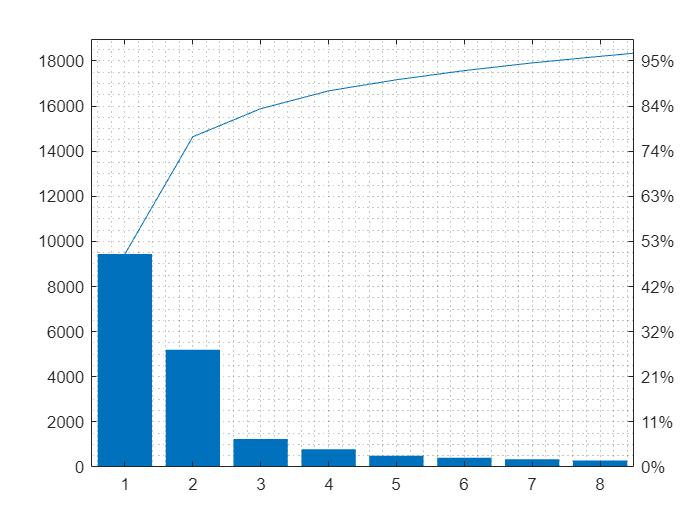

pd = pdist(statsNorm);
[Y, e] = cmdscale(pd);
pareto(e)
grid minor

## Task 2

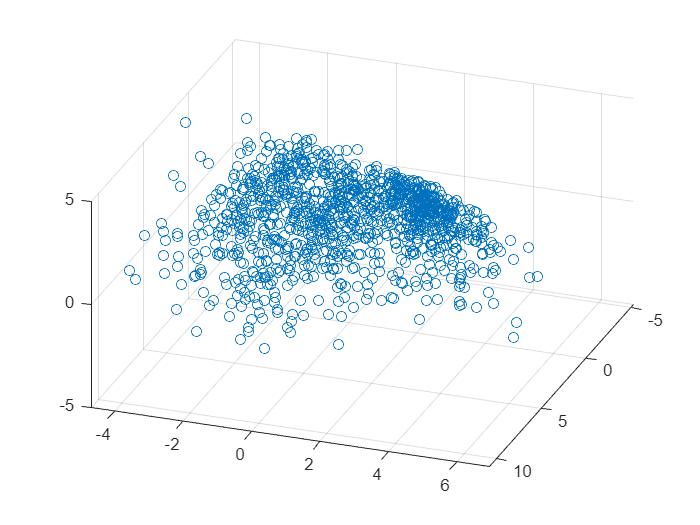

scatter3(Y(:, 1), Y(:, 2), Y(:, 3))
view(110, 40)

## Task 3

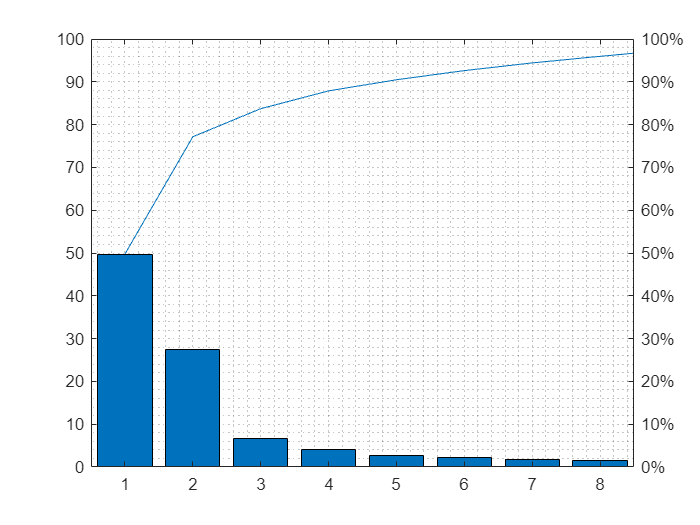

[~, scrs, ~, ~, pexp] = pca(statsNorm);
pareto(pexp)
grid minor

## Task 4

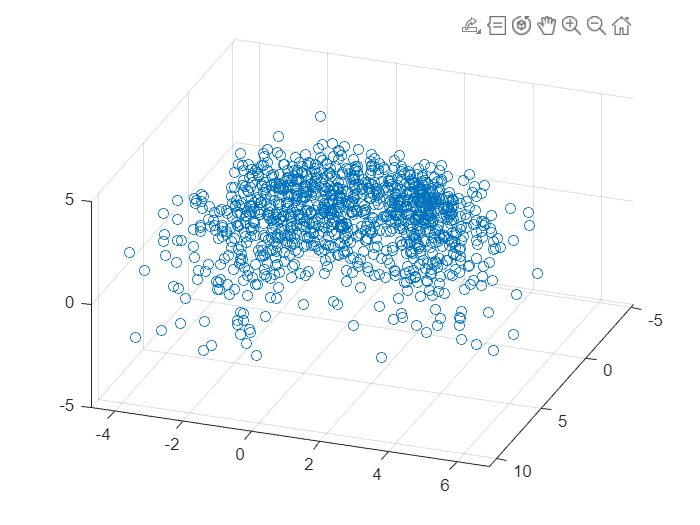

scatter3(scrs(:, 1), scrs(:, 2), scrs(:, 3))
view(110, 40)